% 6.2.2
P1 = [-1 2 -3 6 -3 2 -1];
D1 = [1 zeros(1,6)];
P2 = [3 -2.4 15.36 3.84 9];
D2 = [5 -8.5 17.6 4.7 -6];
P3 = [2 0.2 6.4 4.6 2.4];
D3 = [5 1 6.6 4.2 24];

zeros1 = roots(P1)

zeros1 =    1.8054 + 0.0000i
  -0.1269 + 1.5457i
  -0.1269 - 1.5457i
  -0.0528 + 0.6426i
  -0.0528 - 0.6426i
   0.5539 + 0.0000i


poles1 = roots(D1)

poles1 =      0
     0
     0
     0
     0
     0


% right-sided

zeros2 = roots(P2)

zeros2 =    0.6000 + 2.1541i
   0.6000 - 2.1541i
  -0.2000 + 0.7483i
  -0.2000 - 0.7483i


poles2 = roots(D2)

poles2 =    0.9000 + 1.7861i
   0.9000 - 1.7861i
  -0.6000 + 0.0000i
   0.5000 + 0.0000i



zeros3 = roots(P3)

zeros3 =    0.3296 + 1.7980i
   0.3296 - 1.7980i
  -0.3796 + 0.4637i
  -0.3796 - 0.4637i


poles3 = roots(D3)

poles3 =    0.8272 + 1.2744i
   0.8272 - 1.2744i
  -0.9272 + 1.1045i
  -0.9272 - 1.1045i


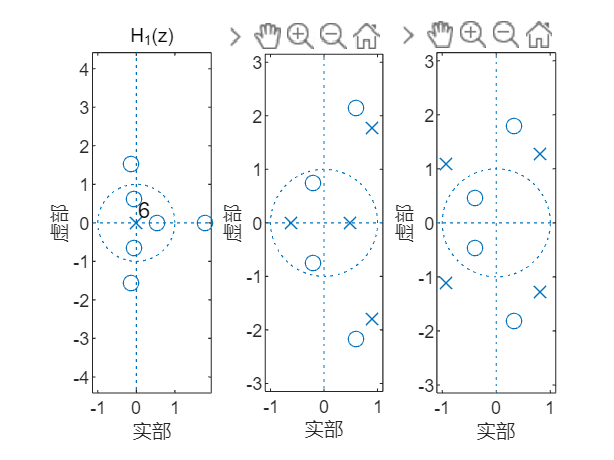


figure
subplot(131),zplane(zeros1,poles1),title('H_1(z)');
subplot(132),zplane(zeros2,poles2),title('G_1(z)');
subplot(133),zplane(zeros3,poles3),title('G_2(z)');

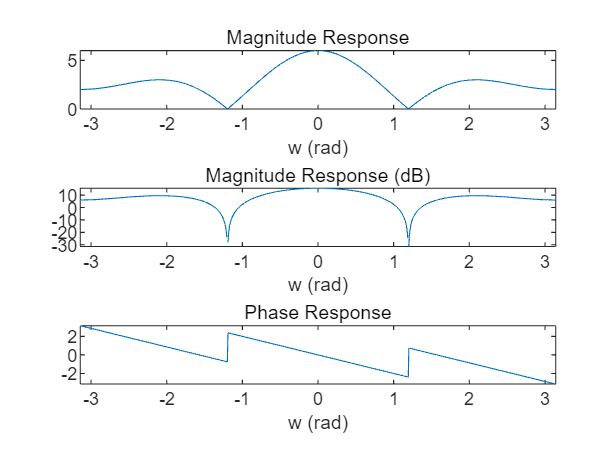

% 6.2.3
FreRes([1 2 0 2 1],1);

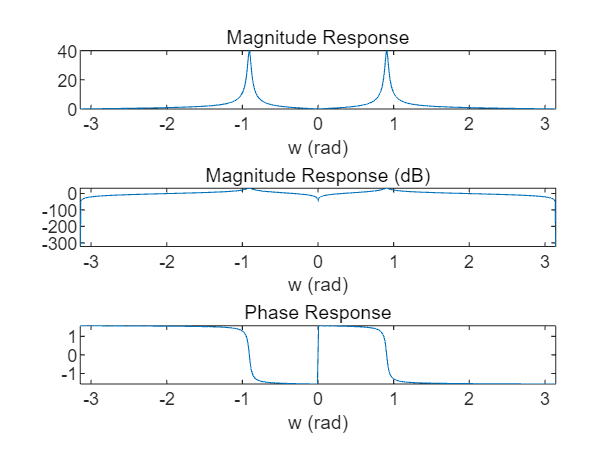

FreRes([1 0 -1],[1 -1.2 0.95]);

% 6.2.4
clear
num1 = [-7.8 3];
den1 = [-1.12 0.9 1];
[r1, p1, k1] = residue(num1, den1);
r1 = r1./(-1.*p1)

r1 =    -2.4783
    5.4783


p1 = 1./(-1.*p1)

p1 =    -0.7000
    1.6000


disp(k1)
num2 = [1.28 1.8 3];
den2 = [-0.2 -0.1 1];
[r2, p2, k2] = residue(num2, den2);
r2 = r2./(-1.*p2)

r2 =     2.8889
    6.5111


p2 = 1./(-1.*p2)

p2 =     0.4000
   -0.5000


disp(k2)

   -6.4000



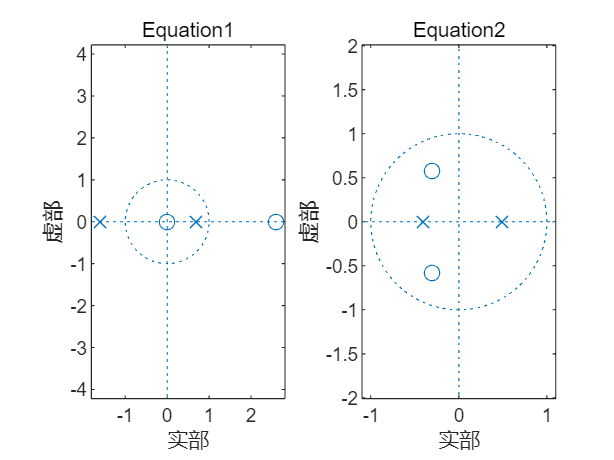

zeros1 = roots([3 -7.8 0]);
poles1 = roots([1 0.9 -1.12]);
zeros2 = roots([3 1.8 1.28]);
poles2 = roots([1 -0.1 -0.2]);
figure
subplot(121),zplane(zeros1,poles1),title('Equation1');
subplot(122),zplane(zeros2,poles2),title('Equation2');

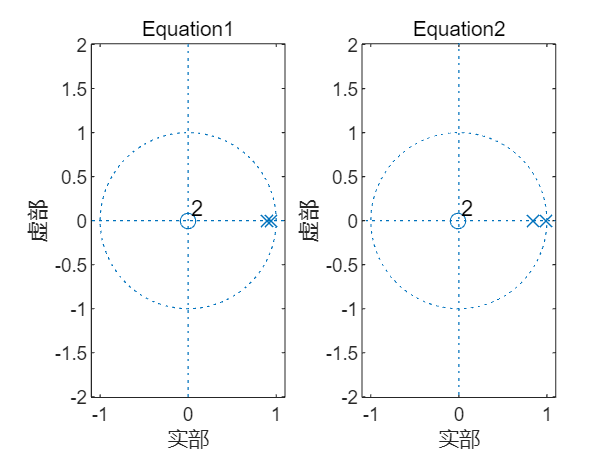

% 6.2.5
zero = roots([1 0 0]);
poles1 = roots([1 -1.845 0.850586]);
poles2 = roots([1 -1.85 0.85]);
figure
subplot(121),zplane(zero,poles1),title('Equation1');
subplot(122),zplane(zero,poles2),title('Equation2');

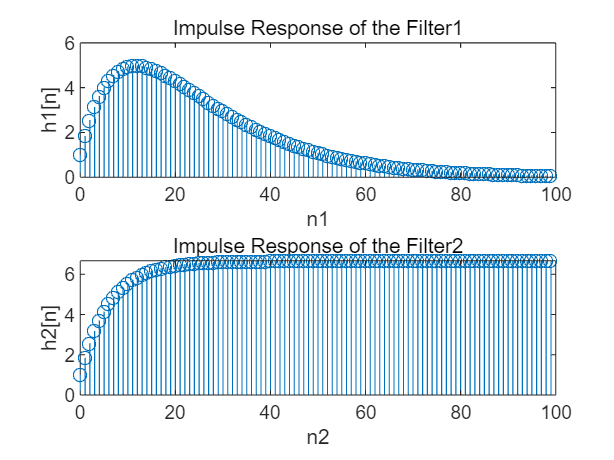


[h1, t1] = impz([1 0 0], [1 -1.845 0.850586], 100);
[h2, t2] = impz([1 0 0], [1 -1.85 0.85], 100);
figure
subplot(211)
stem(t1, h1); 
title('Impulse Response of the Filter1');
xlabel('n1');
ylabel('h1[n]');
subplot(212)
stem(t2, h2); 
title('Impulse Response of the Filter2');
xlabel('n2');
ylabel('h2[n]');

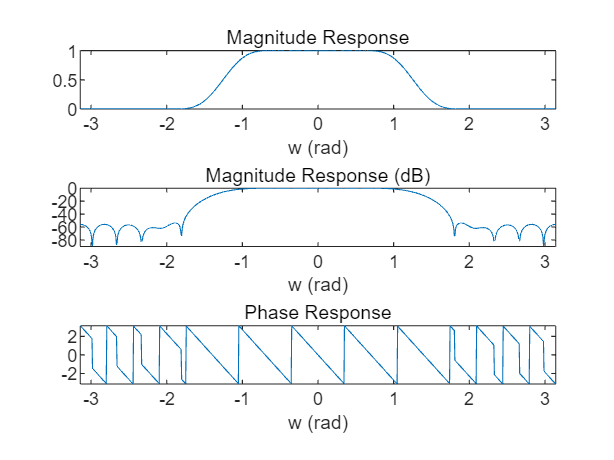

% 6.3.1
clear
h=[-0.0035, -0.0039, 0.0072, 0.0201, -0.0000, -0.0517, -0.0506, 0.0855, 0.2965, 0.4008, 0.2965, 0.0855, -0.0506, -0.0517, -0.0000, 0.0201, 0.0072, -0.0039, -0.0035];
FreRes(h, [1, zeros(1,18)]);

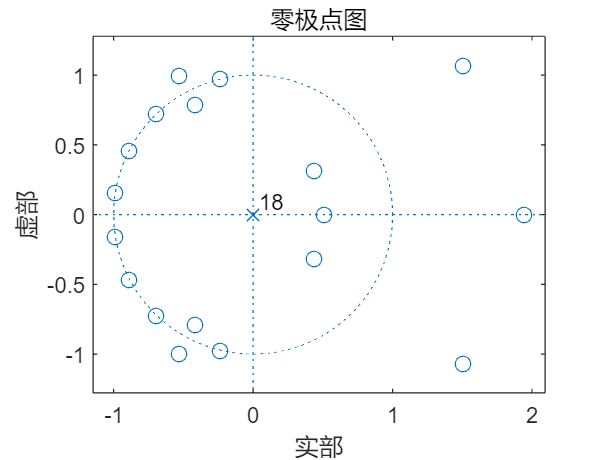

z = roots(h);
p = roots([1,zeros(1,18)]);
figure
zplane(z,p)

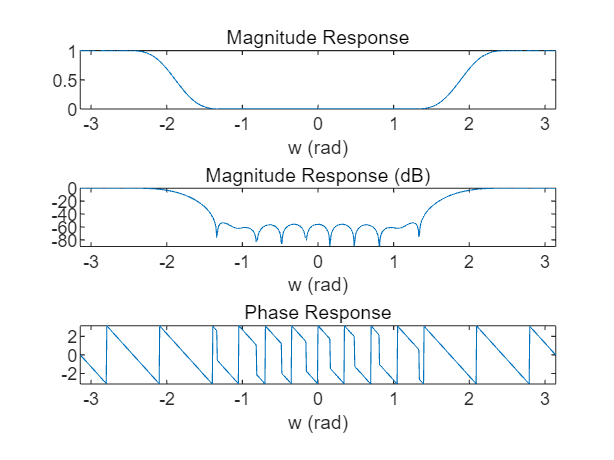

n=0:18;
h1=(-1).^n .*h;
h2=zeros(1,91);
h2(1:5:91)=h(1:1:19);
figure
FreRes(h1, [1, zeros(1,18)]);

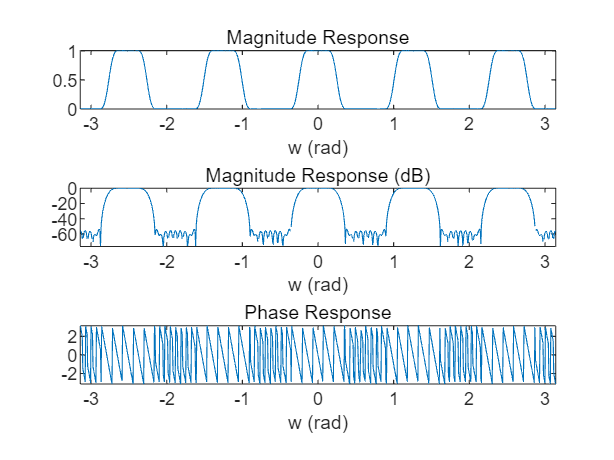

FreRes(h2, [1, zeros(1,90)]);

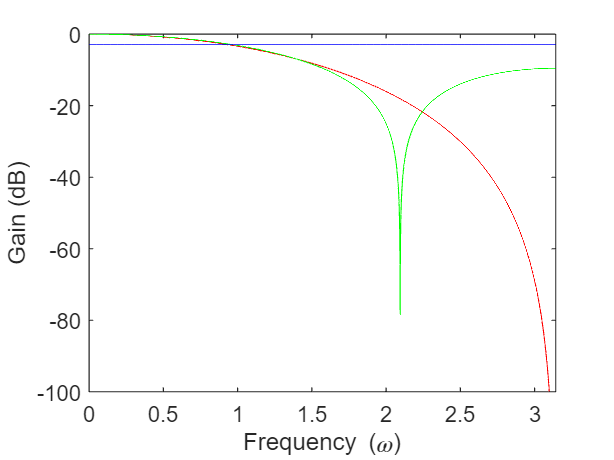

% 6.3.2
M = 3;
w = linspace(0, pi, 5000);
H_cascade = (exp(-1i*w/2).*cos(w/2)).^M;
H_moving_average = (1/M) * sin(M .* w / 2) ./ sin(w / 2) .* exp(-1j * (M-1) .* w / 2);
figure
plot(w, 20 * log10(abs(H_cascade)),'r');
hold on;
plot(w, 20 * log10(abs(H_moving_average)),'g');
plot(w, -3 * ones(1, 5000),'b');
xlabel('Frequency (\omega)');
ylabel('Gain (dB)');
%legend('Cascade Filter', 'Higher Order Moving Average Filter', '3-dB Cutoff Line');
ylim([-100,0])

% 6.4
w = linspace(0, pi, 5000);
wc=0.2*pi;
a = (1-sin(wc))/cos(wc)

a = 0.5095

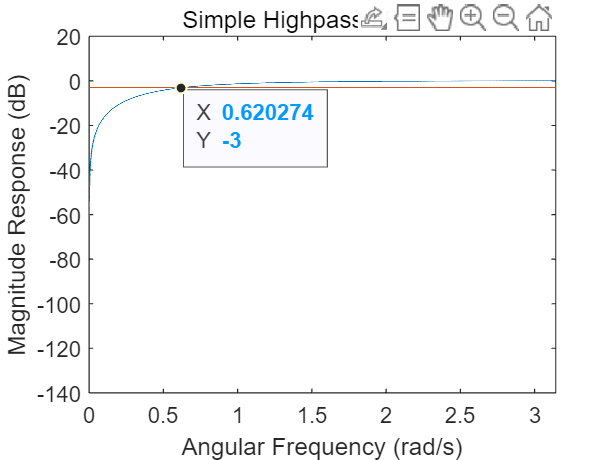

H_mag = sqrt(((1+a)^2*(1-cos(w)))./(2*(1+a^2-2*a*cos(w))));
figure
plot(w, 20 * log10(abs(H_mag)));
hold on;
plot(w, -3 * ones(1, 5000));
xlabel('Angular Frequency (rad/s)');
ylabel('Magnitude Response (dB)');
title('Simple Highpass IIR Filter');
ylim([-140,20])

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,0.6203,-3);

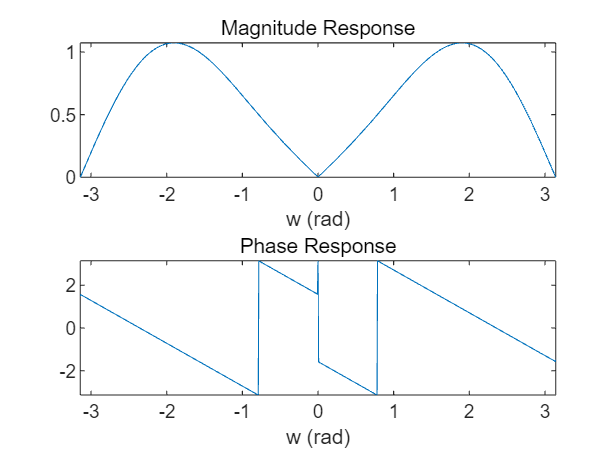

h = [(-1+sqrt(2))/4,-1/2,0,1/2,-(-z1+sqrt(2))/4];
[mag,a,a1,a2] = FreRes(h, [1,zeros(1,3)]);

var1 = double(a1)

var1 = 0.5000

var2 = double(a2)

var2 = 1